% Principal Component Analysis of whole brain using Aya's EEG dataset
% across time.
clear;

if exist('H:\', 'dir')  % If H:\ exists, assume this is Computer 1
    input_path = 'H:\My Drive\Data\New Data\EEG epoched\BLA';
    output_path = 'C:\Users\sinad\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results';

elseif exist('G:\', 'dir')  % If G:\ exists, assume this is Computer 2
    input_path = 'G:\My Drive\Data\New Data\EEG epoched\BLA';
    output_path = 'C:\Users\sdabiri\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results';
else
    error('Unknown system: Cannot determine input and output paths.');
end
% 1- ICA on preprocessed epoched data
% What preprocessing has been done:
% - First prototype the pipeline for BLA (baseline auditory condidtion) for
% the first subject. 
% - Import .set file
file_path = fullfile(input_path,'binepochs filtered ICArej BLAAvgBOS2.set');
EEG = pop_loadset(file_path);

pop_loadset(): loading file H:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS2.set ...


Reading float file 'H:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS2.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


% 2- PCA 
% - 2.1 PCA across space: across IC space

% For the BLA, BLT and P1, we choose the odd epochs to correspond with
% auditory onset, and even epochs to correspond with tactile onset.
% Extract relevant parameters
fs = EEG.srate; % Sampling rate
time_vector = linspace(-0.5, 3, size(EEG.data, 2)); % Time axis (-500ms to 3000ms)

% - Bandpass filter different EEG bands (theta, alpha, beta, gamma): Here
% we will first focus on beta for its role in attention.
epoch_trials = 1:2:EEG.trials; % Select odd trials
num_trials = length(epoch_trials);

data = EEG.data(:, :, epoch_trials);

% Bandpass filter beta band (13-30 Hz)
beta_band = [13 30];
beta_signal = zeros(size(data)); % Preallocate
for epoch = 1:size(data, 3)
    beta_signal(:,:,epoch) = bandpass(data(:,:,epoch)', beta_band, fs)';
end

% % Define pre- and post-stimulus time windows (400ms before and after stimulus onset at 1020ms)
% % 512 sample/sec x 0.4 sec = 204.8
% % Load trial numbers from Excel file
% file_path = 'H:\My Drive\Data\New Data\EEG epoched\Indexes for P3.xlsx'; 
% 
% % Read data for both conditions
% trials_500ms = readmatrix(file_path, 'Sheet', 'Audio onset with 500 ms tactile');
% trials_missing = readmatrix(file_path, 'Sheet', 'Audio onset with missing tactil');

% Define pre-stimulus window (same for both conditions)
pre_window = [-0.4, 0];
post_window = [0, 0.4];

% % Initialize post-stimulus window variable
% post_window = [];
% 
% % Loop through trials
% for trial = 1:EEG.trials
%     if ismember(trial, trials_500ms)
%         post_window = [0, 1.020];  % 500ms condition
%     elseif ismember(trial, trials_missing)
%         post_window = [0, 1.020];  % 1020ms for missing tactile condition
%     else
%         continue; % Skip trials not in either list
%     end
% 
%     % Now you can process the trial using pre_window and post_window
%     % fprintf('Trial %d: Post window set to [%f, %f]\n', trial, post_window(1), post_window(2));
% end
% Convert time to indices
pre_idx = find(time_vector >= pre_window(1) & time_vector <= pre_window(2));
post_idx = find(time_vector >= post_window(1) & time_vector <= post_window(2));

% Initialize results matrix (Trials x PCs)
pc_diff_squared = zeros(num_trials, 32); % Assuming 32 PCs

% Initialize matrix for normalized values
pc_diff_squared_z = zeros(size(pc_diff_squared));

% Loop through each selected trial
for i = 1:num_trials
    trial_data = squeeze(beta_signal(:, :, i)); % Channels x Time

    % Perform PCA on the trial
    [coeff, score, ~] = pca(trial_data'); % Time x Channels -> PCA
    
    % Extract PCs within time windows
    pre_pcs = score(pre_idx, :); % Pre-stimulus PCs
    post_pcs = score(post_idx, :); % Post-stimulus PCs

    % Compute difference, sum, and square
    pc_diff = sum(post_pcs, 1) - sum(pre_pcs, 1); % Sum across time, subtract pre from post
    pc_diff_squared(i,:) = pc_diff.^2; % Square

    pc_mean = mean(pc_diff_squared(i, :));  % Mean across PCs for this trial
    pc_std = std(pc_diff_squared(i, :));   % Standard deviation across PCs for this trial
    
    % Avoid division by zero
    if pc_std == 0
        pc_std = 1;
    end
    
    % Compute z-score normalized values within the trial
    pc_diff_squared_z(i, :) = (pc_diff_squared(i, :) - pc_mean) / pc_std;
end


% 
% % Normalize across PCs within each trial
% for i = 1:num_trials
%     pc_mean = mean(pc_diff_squared(i, :));  % Mean across PCs for this trial
%     pc_std = std(pc_diff_squared(i, :));   % Standard deviation across PCs for this trial
%     
%     % Avoid division by zero
%     if pc_std == 0
%         pc_std = 1;
%     end
%     
%     % Compute z-score normalized values within the trial
%     pc_diff_squared_z(i, :) = (pc_diff_squared(i, :) - pc_mean) / pc_std;
% end

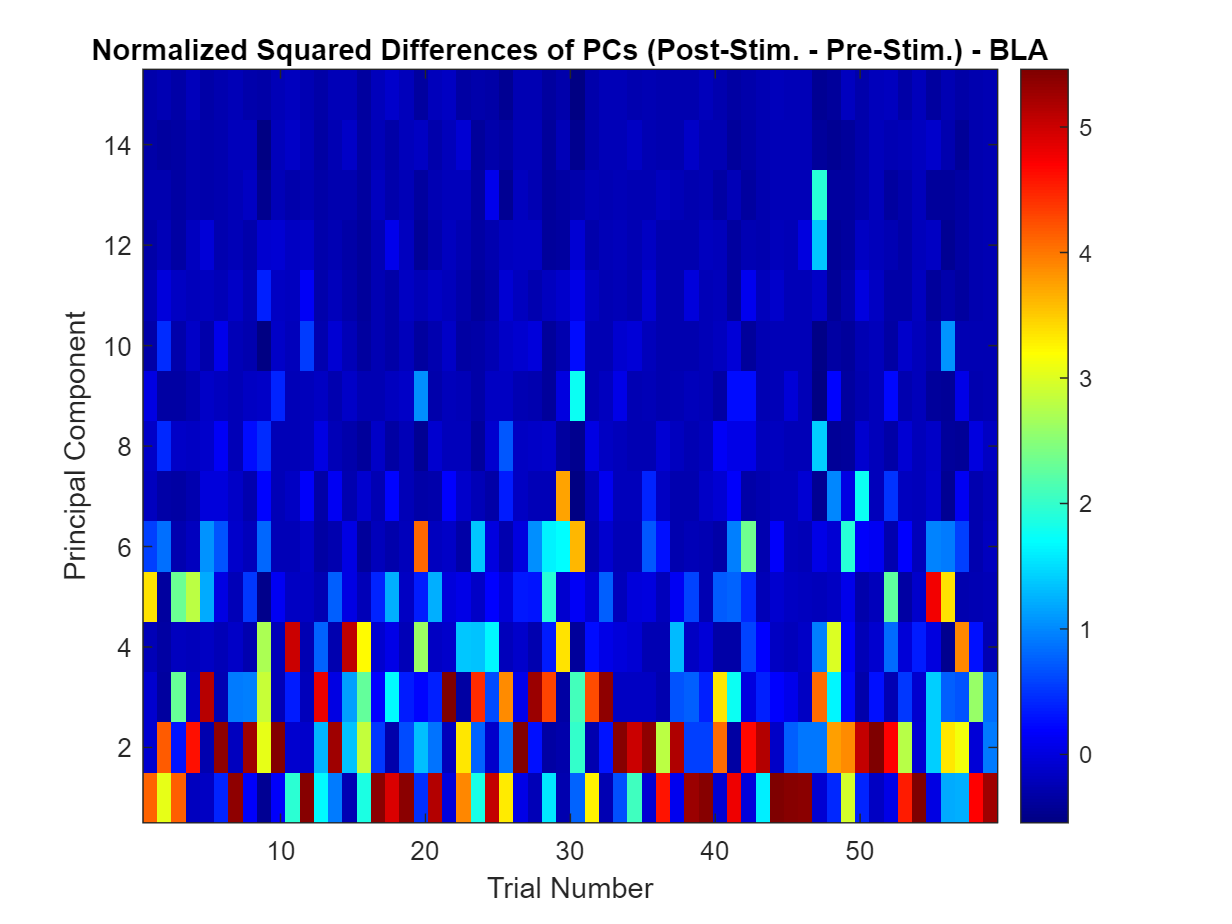

% Plot as heatmap
figure;
imagesc(1:length(epoch_trials)-1, 1:15, pc_diff_squared_z(:,1:15)'); % Transpose so PCs are on the y-axis
colorbar;
xlabel('Trial Number');
ylabel('Principal Component');
title(['Normalized Squared Differences of PCs (Post-Stim. - Pre-Stim.) - ' 'BLA']);
set(gca, 'YDir', 'normal'); % Ensure correct orientation
colormap jet;

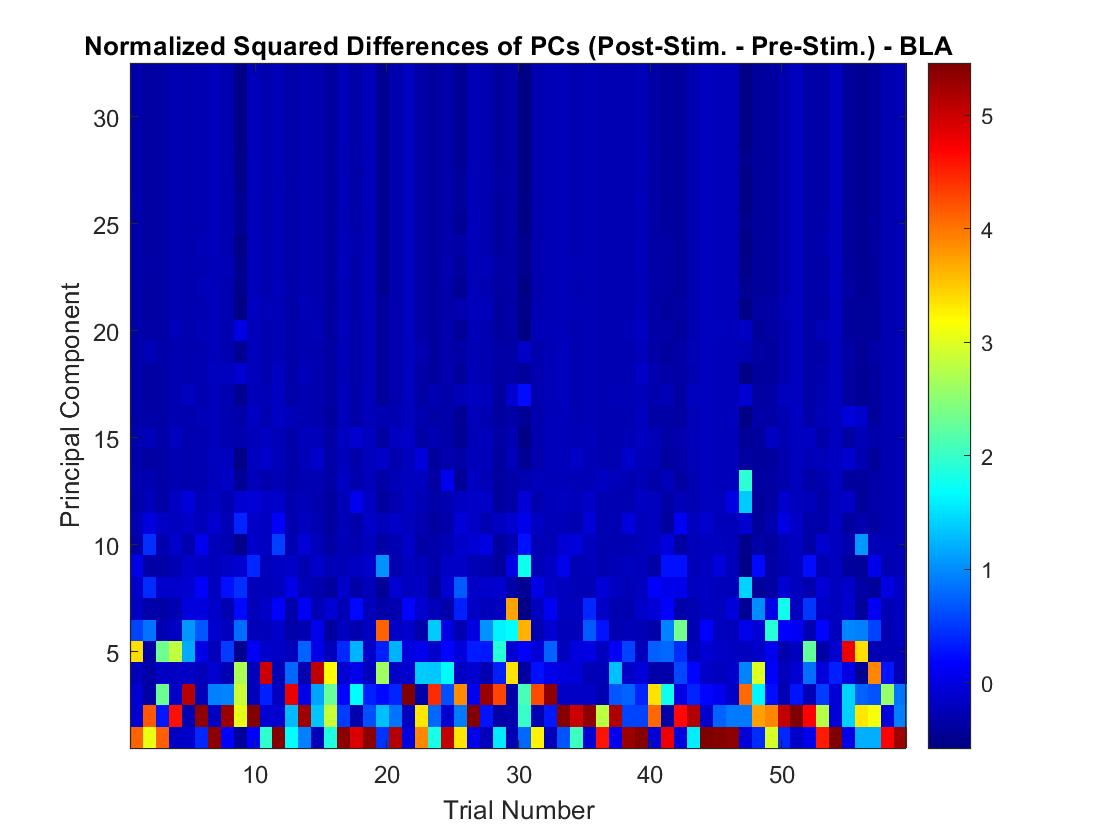

% Plot as heatmap
figure;
imagesc(1:length(epoch_trials)-1, 1:(length(pc_diff)), pc_diff_squared_z'); % Transpose so PCs are on the y-axis
colorbar;
xlabel('Trial Number');
ylabel('Principal Component');
title(['Normalized Squared Differences of PCs (Post-Stim. - Pre-Stim.) - ' 'BLA']);
set(gca, 'YDir', 'normal'); % Ensure correct orientation
colormap jet;